# Real-Time Facial Recognition Using HOG Features

Kevin Chng

Application Engineer

## Overview :

              This example demonstrates how to register a new face, label new face, extract features and recognise the face in real time.It is a very interesting topic. However, in this example, we are not particular in the accuracy, instead of that, i'm demonstrating the workflow. In order to increase the accuracy, we might need to extract more features for machine learning. 

There are many examples available online, some links are provided below, you may take a look at their example.

Example 1: How to activate your webcam

[https://www.mathworks.com/videos/webcam-support-89504.html](https://www.mathworks.com/videos/webcam-support-89504.html)

Example 2 : Face Detection and Tracking Using Live Video Acquisition

[https://www.mathworks.com/help/vision/examples/face-detection-and-tracking-using-live-video-acquisition.html](https://www.mathworks.com/help/vision/examples/face-detection-and-tracking-using-live-video-acquisition.html)

Example 3: Code for Face Recognition with MATLAB Webinar

video : [https://www.mathworks.com/videos/face-recognition-with-matlab-100902.html](https://www.mathworks.com/videos/face-recognition-with-matlab-100902.html)

Example 4 : Detecting Faces in Image

[https://blogs.mathworks.com/pick/2014/03/14/detecting-faces-in-images/](https://blogs.mathworks.com/pick/2014/03/14/detecting-faces-in-images/)

Example 5 : Facial Recognition using Kekre transform

[https://www.mathworks.com/matlabcentral/fileexchange/32284-face-recognition-system-using-kekre-transform](https://www.mathworks.com/matlabcentral/fileexchange/32284-face-recognition-system-using-kekre-transform)

Example 6 : Real-time Face Recogn

[https://www.mathworks.com/matlabcentral/fileexchange/46674-real-time-face-recognition-and-detection-system](https://www.mathworks.com/matlabcentral/fileexchange/46674-real-time-face-recognition-and-detection-system)

Example 7 : Creating a Cloud Based People Counter Using MATLAB (ThingSpeak)

[https://www.mathworks.com/matlabcentral/fileexchange/58435-creating-a-cloud-based-people-counter-using-matlab](https://www.mathworks.com/matlabcentral/fileexchange/58435-creating-a-cloud-based-people-counter-using-matlab)

## **Highlights : **

- Registration of New Face in Webcam through Image Acquisition Toolbox

- Label of New Face captured by Webcam

- Extract Features for Machine Learning

- Machine Learning and Prediction 

- Performs Real-Time Facial Recognition

## **Product Focus :**

- MATLAB

- Image Acquisition Toolbox

- Image Processing Toolbox

- Computer Vision System Toolbox

- Machine Learning and Statistic Toolbox

## **Flow :**

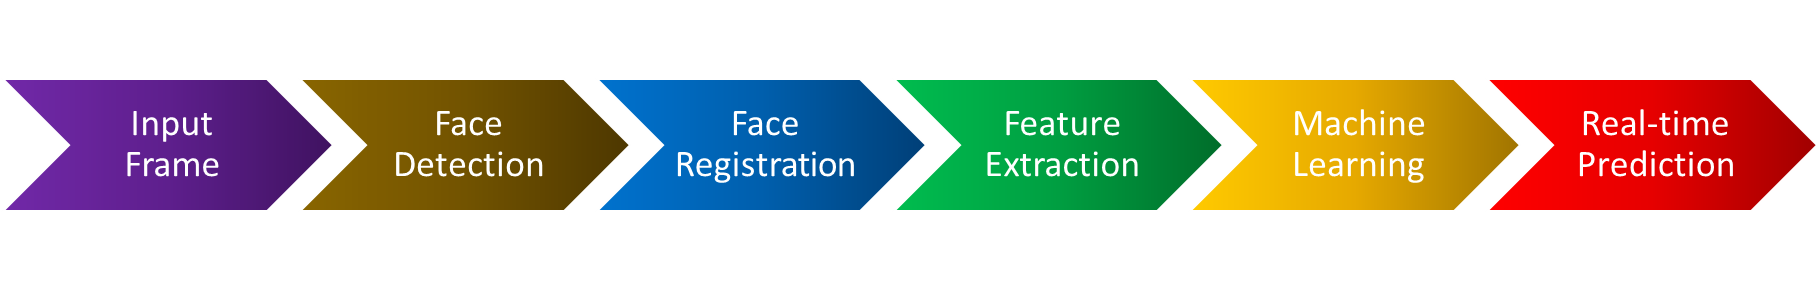

**Written at 1 October 2018**

## **Capture Photo for your user and store it in your Database**

I modified the code from the link : [https://www.mathworks.com/help/vision/examples/face-detection-and-tracking-using-live-video-acquisition.html](https://www.mathworks.com/help/vision/examples/face-detection-and-tracking-using-live-video-acquisition.html)

**Setup**

clc
clear all
close all

% Create the face detector object.
faceDetector = vision.CascadeObjectDetector();

% Create the point tracker object.
pointTracker = vision.PointTracker('MaxBidirectionalError', 2);

% Create the webcam object.
if exist('cam') ==0
cam = webcam('Integrated Camera');
end

% Capture one frame to get its size.
videoFrame = snapshot(cam);
frameSize = size(videoFrame);

% Create the video player object.
videoPlayer = vision.VideoPlayer('Position', [100 100 [frameSize(2), frameSize(1)]+30]);

## **Detection & Tracking**

runLoop = true;
numPts = 0;
frameCount = 0;

while runLoop && frameCount < 100

    % Get the next frame.
    videoFrame = snapshot(cam);
    
    % Get frame to save data to database
    videoFrameGray = rgb2gray(videoFrame);
    frameCount = frameCount + 1;

    if numPts < 10
        % Detection mode.
        bbox = faceDetector.step(videoFrameGray);

        if ~isempty(bbox)
            % Find corner points inside the detected region.
            points = detectMinEigenFeatures(videoFrameGray, 'ROI', bbox(1, :));

            % Re-initialize the point tracker.
            xyPoints = points.Location;
            numPts = size(xyPoints,1);
            release(pointTracker);
            initialize(pointTracker, xyPoints, videoFrameGray);

            % Save a copy of the points.
            oldPoints = xyPoints;

            % Convert the rectangle represented as [x, y, w, h] into an
            % M-by-2 matrix of [x,y] coordinates of the four corners. This
            % is needed to be able to transform the bounding box to display
            % the orientation of the face.
            bboxPoints = bbox2points(bbox(1, :));

            % Convert the box corners into the [x1 y1 x2 y2 x3 y3 x4 y4]
            % format required by insertShape.
            bboxPolygon = reshape(bboxPoints', 1, []);

            % Display a bounding box around the detected face.
            videoFrame = insertShape(videoFrame, 'Polygon', bboxPolygon, 'LineWidth', 3);

            % Display detected corners.
            videoFrame = insertMarker(videoFrame, xyPoints, '+', 'Color', 'white');
        end

    else
        % Tracking mode.
        [xyPoints, isFound] = step(pointTracker, videoFrameGray);
        visiblePoints = xyPoints(isFound, :);
        oldInliers = oldPoints(isFound, :);

        numPts = size(visiblePoints, 1);

        if numPts >= 10
            % Estimate the geometric transformation between the old points
            % and the new points.
            [xform, oldInliers, visiblePoints] = estimateGeometricTransform(...
                oldInliers, visiblePoints, 'similarity', 'MaxDistance', 4);

            % Apply the transformation to the bounding box.
            bboxPoints = transformPointsForward(xform, bboxPoints);

            % Convert the box corners into the [x1 y1 x2 y2 x3 y3 x4 y4]
            % format required by insertShape.
            bboxPolygon = reshape(bboxPoints', 1, []);
            
            % Display a bounding box around the face being tracked.
            videoFrame = insertShape(videoFrame, 'Polygon', bboxPolygon, 'LineWidth', 3);

            % Display tracked points.
            videoFrame = insertMarker(videoFrame, visiblePoints, '+', 'Color', 'white');

            % Reset the points.
            oldPoints = visiblePoints;
            setPoints(pointTracker, oldPoints);
        end

    end

    % Display the annotated video frame using the video player object.
    step(videoPlayer, videoFrame);

    % Check whether the video player window has been closed.
    runLoop = isOpen(videoPlayer);
end

% Clean up.
clear cam;
release(videoPlayer);
release(pointTracker);
release(faceDetector);

## **Save your image to your database**

You have to repeat it from step 1 to here to save more face either same person or different person.

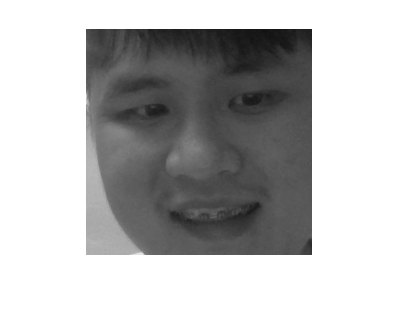

position1 = min(bboxPolygon(2),bboxPolygon(4));
position2 = max(bboxPolygon(6),bboxPolygon(8));
position3 = min(bboxPolygon(1),bboxPolygon(7));
position4 = max(bboxPolygon(3),bboxPolygon(5));

warning('off')
getimage = videoFrameGray(position1:position2,position3:position4,:);
imshow(getimage)

%resize image
getimage = imresize(getimage, [300 300]);

% Modify here. In the folder database2, label the name of ppl and put their
% faces inside the folder.
imwrite(getimage,'database2\Jay Chou\10.jpg');

Label the folder with the name of people, and put their photo in their folder. This part is labelling.

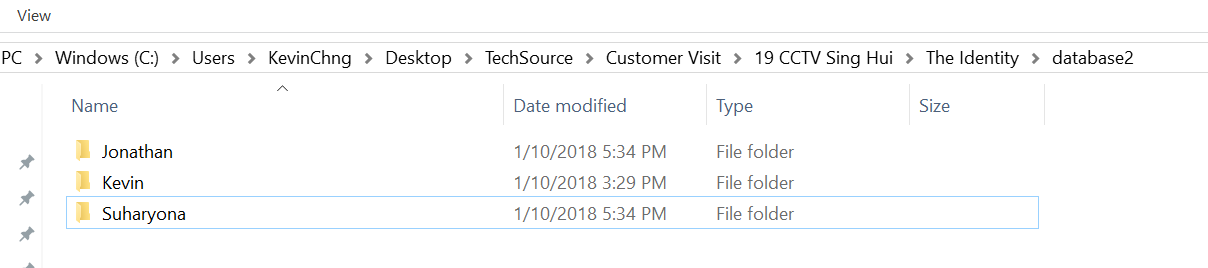

## **Train your Image in the database folder**

Train the image your database. I modified the code from the link :  [https://www.mathworks.com/matlabcentral/fileexchange/53849-code-for-face-recognition-with-matlab-webinar](https://www.mathworks.com/matlabcentral/fileexchange/53849-code-for-face-recognition-with-matlab-webinar)

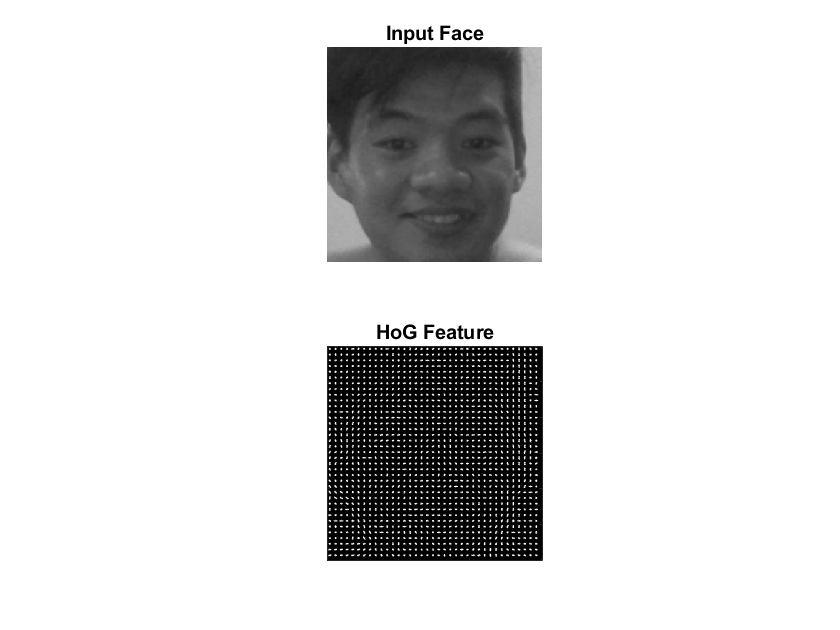

%% Load Image Information from ATT Face Database Directory
faceDatabase = imageSet('database2','recursive');

%% Split Database into Training & Test Sets
[training,test] = partition(faceDatabase,[0.8 0.2]);

%% Extract and display Histogram of Oriented Gradient Features for single face 
person = 2;
[hogFeature, visualization]= ...
    extractHOGFeatures(read(training(person),1));
figure;
subplot(2,1,1);imshow(read(training(person),1));title('Input Face');
subplot(2,1,2);plot(visualization);title('HoG Feature');


% Extract HOG Features for training set 
trainingFeatures = zeros(size(training,2)*training(1).Count,46656);
featureCount = 1;
for i=1:size(training,2)
    for j = 1:training(i).Count
        points = detectSURFFeatures(read(training(i),j));
        trainingFeatures(featureCount,:) = extractHOGFeatures(read(training(i),j));
        trainingLabel{featureCount} = training(i).Description;    
        featureCount = featureCount + 1;
    end
    personIndex{i} = training(i).Description;
end
% Create 40 class classifier using  
faceClassifier = fitcecoc(trainingFeatures,trainingLabel);

## **Predict Person in the database folder**

I modified the code from the link : [https://www.mathworks.com/help/vision/examples/face-detection-and-tracking-using-live-video-acquisition.html](https://www.mathworks.com/help/vision/examples/face-detection-and-tracking-using-live-video-acquisition.html)

**Setup**

% Create the face detector object.
faceDetector = vision.CascadeObjectDetector();

% Create the point tracker object.
pointTracker = vision.PointTracker('MaxBidirectionalError', 2);

% Create the webcam object.
if exist('cam') ==0
cam = webcam('Integrated Camera');
end
% Capture one frame to get its size.
videoFrame = snapshot(cam);
frameSize = size(videoFrame);

% Create the video player object.
videoPlayer = vision.VideoPlayer('Position', [100 100 [frameSize(2), frameSize(1)]+30]);

**Run Video for Prediction**

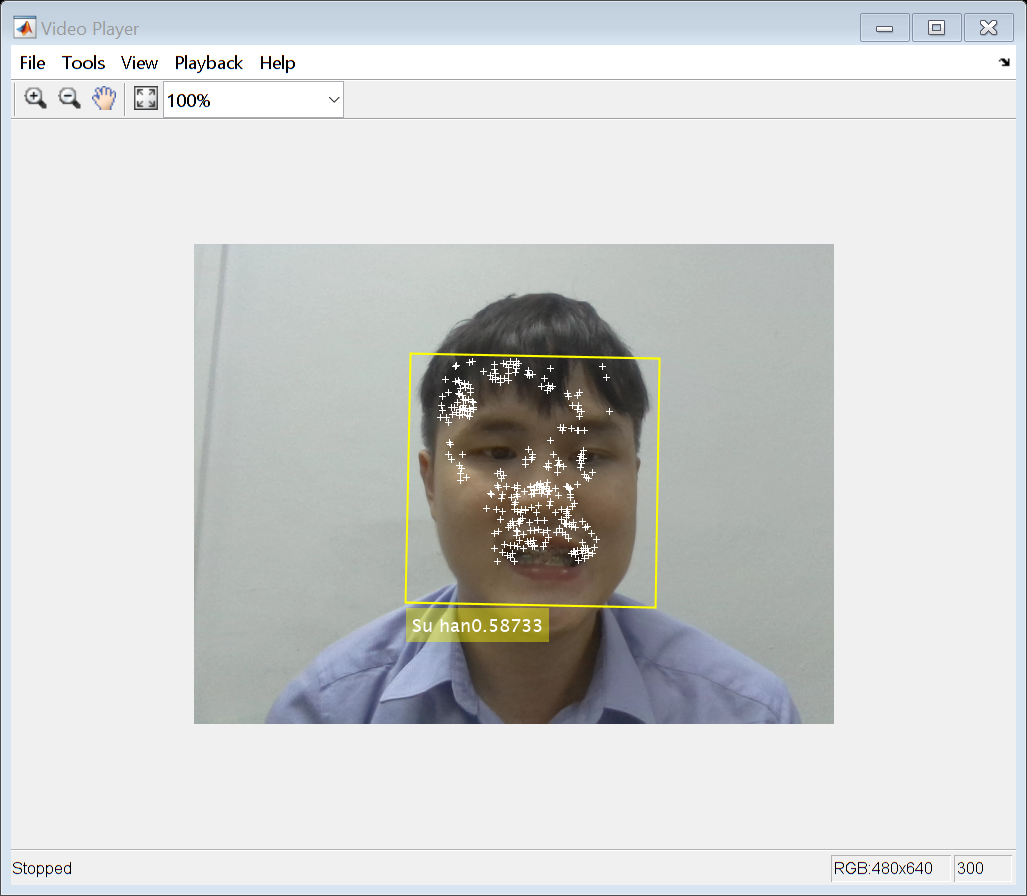

runLoop = true;
numPts = 0;
frameCount = 0;
%cam = webcam('Integrated Camera');
while runLoop && frameCount < 300

    % Get the next frame.
    videoFrame = snapshot(cam);
    
    % Get frame to save data to database
    videoFrame2 = snapshot(cam);
    videoFrameGray = rgb2gray(videoFrame);
    frameCount = frameCount + 1;

    if numPts < 10
        % Detection mode.
        bbox = faceDetector.step(videoFrameGray);

        if ~isempty(bbox)
            % Find corner points inside the detected region.
            points = detectMinEigenFeatures(videoFrameGray, 'ROI', bbox(1, :));

            % Re-initialize the point tracker.
            xyPoints = points.Location;
            numPts = size(xyPoints,1);
            release(pointTracker);
            initialize(pointTracker, xyPoints, videoFrameGray);

            % Save a copy of the points.
            oldPoints = xyPoints;

            % Convert the rectangle represented as [x, y, w, h] into an
            % M-by-2 matrix of [x,y] coordinates of the four corners. This
            % is needed to be able to transform the bounding box to display
            % the orientation of the face.
            bboxPoints = bbox2points(bbox(1, :));

            % Convert the box corners into the [x1 y1 x2 y2 x3 y3 x4 y4]
            % format required by insertShape.
            bboxPolygon = reshape(bboxPoints', 1, []);

            % Display a bounding box around the detected face.
            videoFrame = insertShape(videoFrame, 'Polygon', bboxPolygon, 'LineWidth', 3);

            % Display detected corners.
            videoFrame = insertMarker(videoFrame, xyPoints, '+', 'Color', 'white');
        end

    else
        % Tracking mode.
        [xyPoints, isFound] = step(pointTracker, videoFrameGray);
        visiblePoints = xyPoints(isFound, :);
        oldInliers = oldPoints(isFound, :);

        numPts = size(visiblePoints, 1);

        if numPts >= 10
            
            % Estimate the geometric transformation between the old points
            % and the new points.
            [xform, oldInliers, visiblePoints] = estimateGeometricTransform(...
                oldInliers, visiblePoints, 'similarity', 'MaxDistance', 4);

            % Apply the transformation to the bounding box.
            bboxPoints = transformPointsForward(xform, bboxPoints);


            % Convert the box corners into the [x1 y1 x2 y2 x3 y3 x4 y4]
            % format required by insertShape.
            bboxPolygon = reshape(bboxPoints', 1, []);
            
            % Display a bounding box around the face being tracked.
            videoFrame = insertShape(videoFrame, 'Polygon', bboxPolygon, 'LineWidth', 3);

            % Display tracked points.
            videoFrame = insertMarker(videoFrame, visiblePoints, '+', 'Color', 'white');

            % Reset the points.
            oldPoints = visiblePoints;
            setPoints(pointTracker, oldPoints);
            
            position1 = min(bboxPolygon(2),bboxPolygon(4));
            position2 = max(bboxPolygon(6),bboxPolygon(8));
            position3 = min(bboxPolygon(1),bboxPolygon(7));
            position4 = max(bboxPolygon(3),bboxPolygon(5));
            
            warning('off')
            if position2<640 && position4<640 && position1>0 && position2>0
            getimage = videoFrameGray(position1:position2,position3:position4,:);

            %resize image
            getimage = imresize(getimage, [300 300]);

            
            queryFeatures = extractHOGFeatures(getimage);
            [personLabel,PostProbs]  = predict(faceClassifier,queryFeatures);
            maxpro = max(abs(PostProbs(1)),abs(PostProbs(2)));
            position = [position3 position2];
            box_color = {'yellow'};
            string = strcat(personLabel,num2str(maxpro));
            videoFrame = insertText(videoFrame,position,string,'FontSize',18,'BoxColor',...
            box_color,'BoxOpacity',0.4,'TextColor','white');
            end
        end

    end

    % Display the annotated video frame using the video player object.
    step(videoPlayer, videoFrame);

    % Check whether the video player window has been closed.
    runLoop = isOpen(videoPlayer);
end
% Clean up.
clear cam;
release(videoPlayer);

release(pointTracker);
release(faceDetector);

## **Conclusion**

There are many examples avilable online. If you have any doubt, you may google it. 

In order to increase the accuracy, you may insert larger dataset, extract more facial features for machine learning, consider other machine learning model, or even try deep learning. 